N_elements = 16; 
u_points = 91; %-90：2：90
v_points = 19; %0:5:180
theta = -90:2:90;
phi = 0:10:180;

f_list = 20;
f_points = size(f_list, 2);
G_complex_all = zeros(u_points*v_points, 2, f_points, N_elements);% 
datafolder = "dataset\\planar_cp_dataset\\";

% 构建二维小阵列
for iter = 397:500

    numPoints = 16;
    R = 0.20; % 设置最小距离
    
    points = generatePointsWithMinDistance(numPoints, R);
        
    Lx = 2.5*15;
    Ly = 2.5*15;
    model_points{1} = points(1:16, :) .* [Lx, Ly] - [Lx/2, Ly/2];
    model_points{2} = [];
    model(model_points, "array-planar-cp");

    for k = 1:16
        [gn_complex_k, angles_uv] = get_AEP_HFSS_xy(k, [0,0,0], model_points{1}, 20);
          G_complex_all(:,:,:, k) = gn_complex_k;
    end
   
    delete(16,"array-planar-cp");
    filename = sprintf(datafolder + "Gn_%d", iter);
    save(filename + ".mat","G_complex_all","model_points");
end

model(model_points, "array-planar-cp");

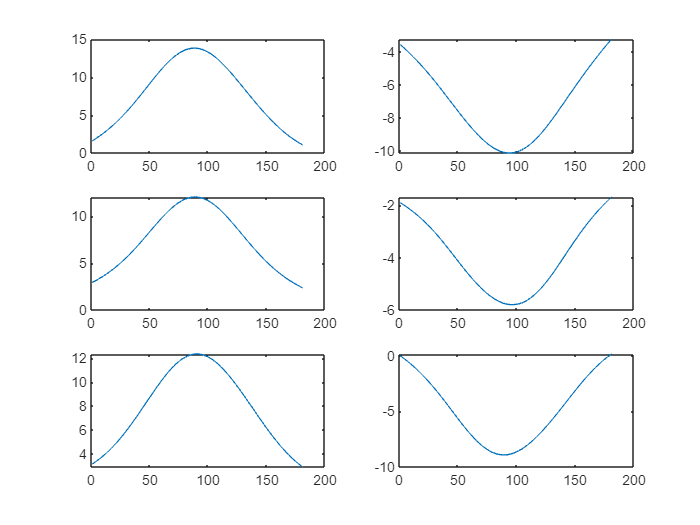

%% 
i=10;
for f = 7
    E_theta = G_complex_all(:,1,f,i);
    E_phi = G_complex_all(:,2,f,i);
%     plot(abs(E_theta));
    Er = 1/sqrt(2) * (E_theta + 1j*E_phi);
%     plot(imag(Er));
%     figure (2);hold on;
    subplot(3,2,1);plot(real(Er));
    subplot(3,2,2);plot(imag(Er));
    subplot(3,2,3);plot(abs(E_theta));
    subplot(3,2,4);plot(imag(E_theta));
    subplot(3,2,5);plot(abs(E_phi));
    subplot(3,2,6);plot(imag(E_phi));
end

% validate data
theta_scandeg = 0;
phi_scandeg = 0;
u0 = [0,0,0];
u0(1) = sind(theta_scandeg) * cosd(phi_scandeg);
u0(2) = sind(theta_scandeg) * sind(phi_scandeg);

sample = 1:91;
theta = -90:2:90;F = zeros(91,8);
theta_expect = -90:0.5:90;
N = 16;
points = model_points{1};
freq = f_list(f);
k0 = 2*pi * freq * 1e9 / 3e8;
for n = 1:N
    rn = [points(n,:)/1000,0];
%     Gn(:,1) = YPred_theta_complex(:, n);
%     Gn(:,2) = YPred_phi_complex(:, n);
%     Gn(:,3) = 1/sqrt(2) * (YPred_theta_complex(:, n) + 1j*YPred_phi_complex(:,n));% 
%     Gn(:,4) = 1/sqrt(2) * (YPred_theta_complex(:, n) - 1j*YPred_phi_complex(:,n));


    Gn(:,5) = G_complex_all(sample,1,1, n);
    Gn(:,6) = G_complex_all(sample,2,1, n);
    Gn(:,7) = 1/sqrt(2) * (G_complex_all(sample,1,f, n) + 1j*G_complex_all(sample,2,f,n));
    Gn(:,8) = 1/sqrt(2) * (G_complex_all(sample,1,f, n) - 1j*G_complex_all(sample,2,f,n));
%     Gn3 = gn_periodic;
    phase_n = k0 * (-dot(rn, u0));
    for i = 1:8
        F(:,i) = F(:,i) + Gn(:,i) .* exp(1j * k0 * (rn(1) * sind(theta.')) + 1j * phase_n);
    end
end
tao = angle(F(:,8) ./ F(:,7))/2;
Ex = F(:, 5) .* cos(tao) - F(:,6) .* sin(tao);
Ey = F(:, 5) .* sin(tao) + F(:,6) .* cos(tao);
AR = abs(Ey ./ Ex);
AR = interp1(theta,AR, theta_expect, 'spline');
idx = AR<1;
AR(idx) = 1 ./ AR(idx);

figure; box on;hold on;
% plot(theta_expect, 20*log10(AR_Pred));
plot(theta_expect, 20*log10(AR));
title("theta-scan = " + num2str(theta_scandeg));
xlabel('theta');ylabel("AR(dB)");
xlim([-90 90]);ylim([0 20]);

U = abs(F) .^2 /2 /377;
Gain = 4*pi*U/ N; 
Gain = 10 * log10(Gain);
Gain(isnan(Gain)) = -20;
% plot(theta, abs(F) - F_ref);
Gain = interp1(theta,Gain, theta_expect, 'spline');
figure;
hold on;box on;
% plot(theta_expect, Gain(:,3));
plot(theta_expect, Gain(:,7));
% plot(-90:90, GainPlot1.dBRealizedGainRHCP, '--');
xlabel('theta');ylabel("Gain(dB)");
ylim([-20 20]);xlim([-90 90]);title('RHCP ');
figure;
hold on;box on;
% plot(theta_expect, Gain(:,4));
plot(theta_expect, Gain(:,8));
xlabel('theta');ylabel("Gain(dB)");
ylim([-20 20]);xlim([-90 90]);title("LHCP");

%excite
excite(1, model_points{1}, 20, 0, 0, "array-planar-cp");

function excite(excite_element, points, f, input, theta_scandeg, prj)
    fid = fopen('aabb.vbs', 'w+');
    fprintf(fid, 'Dim oAnsoftApp\n');
    fprintf(fid, 'Dim oDesktop\n');
    fprintf(fid, 'Dim oProject\n');
    fprintf(fid, 'Dim oDesign\n');
    fprintf(fid, 'Dim oEditor\n');
    fprintf(fid, 'Dim oModule\n');
    fprintf(fid, 'Set oAnsoftApp = CreateObject("Ansoft.ElectronicsDesktop")\n');
    fprintf(fid, 'Set oDesktop = oAnsoftApp.GetAppDesktop()\n');
    fprintf(fid, 'oDesktop.RestoreWindow\n');
    fprintf(fid, 'Set oProject = oDesktop.SetActiveProject("patch")\n');
    fprintf(fid, 'Set oDesign = oProject.SetActiveDesign("%s")\n', prj);
    fprintf(fid, 'Set oModule = oDesign.GetModule("Solutions")\n');
    fprintf(fid, 'oModule.EditSources Array(Array("IncludePortPostProcessing:=", false, "SpecifySystemPower:=",false)');
    
    N = 16;
    k0 = 2*pi * f * 1e9/ 3e8;phiScanDeg = 0;
    u0 = [sind(theta_scandeg)*cosd(phiScanDeg), sind(theta_scandeg)*sind(phiScanDeg), 0];
    for i = 2:N+1
        rn = [points(i-1,:)/1000,0];
        phase_n = k0 * (-dot(rn, u0));
        if i == excite_element + 1 
            fprintf(fid, ',Array("Name:=", "%d:1", "Magnitude:=", "1W", "Phase:=", "0deg")',i);
        else 
            fprintf(fid, ',Array("Name:=", "%d:1", "Magnitude:=", "%dW", "Phase:=", "%fdeg")',i, input, rad2deg(phase_n));
        end
    end
    fprintf(fid, ')');
    
    fclose all;
    dos 'aabb.vbs';
end
function points = generatePointsWithMinDistance(numPoints, R)
    % 初始化
    points = []; % 存储生成的点
    minDistance = R; % 最小距离
    maxAttempts = 10000; % 最大尝试次数，防止死循环
    bounds = [0, 1, 0, 1]; % 区域范围 [xmin, xmax, ymin, ymax]
    
    attempts = 0; % 当前尝试次数
    
    while size(points, 1) < numPoints && attempts < maxAttempts
        % 随机生成一个候选点
        candidate = [rand, rand]; % 在 [0,1]x[0,1] 范围内生成随机点
        
        % 检查候选点是否满足最小距离要求
        if isempty(points) || all(sqrt(sum((points - candidate).^2, 2)) >= minDistance)
            points = [points; candidate]; % 添加到点集中
        end
        
        attempts = attempts + 1; % 增加尝试计数
    end
    
    % 如果未能生成足够的点，给出警告
    if size(points, 1) < numPoints
        warning('未能生成足够的点，请调整参数或增加尝试次数。');
    end
end

function points = generatePoints_alongX(numPoints, R)
    % 初始化
    points = []; % 存储生成的点
    minDistance = R; % 最小距离
    maxAttempts = 10000; % 最大尝试次数，防止死循环
    
    attempts = 0; % 当前尝试次数
    
    while size(points, 1) < numPoints && attempts < maxAttempts
        % 随机生成一个候选点
        candidate = [rand, 0]; % 在 [0,1]x[0,1] 范围内生成随机点
        
        % 检查候选点是否满足最小距离要求
        if isempty(points) || all(sqrt(sum((points - candidate).^2, 2)) >= minDistance)
            points = [points; candidate]; % 添加到点集中
        end
        
        attempts = attempts + 1; % 增加尝试计数
    end
    
    % 如果未能生成足够的点，给出警告
    if size(points, 1) < numPoints
        warning('未能生成足够的点，请调整参数或增加尝试次数。');
    end
end

function points = generatePoints_alongY(numPoints, R)
    % 初始化
    points = []; % 存储生成的点
    minDistance = R; % 最小距离
    maxAttempts = 10000; % 最大尝试次数，防止死循环
    
    attempts = 0; % 当前尝试次数
    
    while size(points, 1) < numPoints && attempts < maxAttempts
        % 随机生成一个候选点
        candidate = [0, rand]; % 在 [0,1]x[0,1] 范围内生成随机点
        
        % 检查候选点是否满足最小距离要求
        if isempty(points) || all(sqrt(sum((points - candidate).^2, 2)) >= minDistance)
            points = [points; candidate]; % 添加到点集中
        end
        
        attempts = attempts + 1; % 增加尝试计数
    end
    
    % 如果未能生成足够的点，给出警告
    if size(points, 1) < numPoints
        warning('未能生成足够的点，请调整参数或增加尝试次数。');
    end
end

function model(all_points, prj_name)
    % model_com: Controls HFSS via COM to build and analyze a model.
    %
    % Inputs:
    %   all_points: A cell array containing point coordinates for duplication.
    %               all_points{1} for the first set of objects.
    %               all_points{2} for the second set of objects.
    %               Each element (e.g., all_points{1}) is an N x 2 matrix
    %               where N is the number of duplication points, and columns
    %               are x and y coordinates respectively.
    %   prj_name:   The name of the HFSS design to be activated.


    % ----------------------------------------------------------------------
    % Connect to HFSS and get necessary objects
    % ----------------------------------------------------------------------
    hApp = actxserver('Ansoft.ElectronicsDesktop');
    hDesktop = hApp.GetAppDesktop();
    hDesktop.RestoreWindow();
    hProject = hDesktop.SetActiveProject('patch'); % Assumes "patch.aedt" is open
    hDesign = hProject.SetActiveDesign(prj_name);
    hEditor = hDesign.SetActiveEditor('3D Modeler');
    % 转换成model
    hEditor.ChangeProperty({ ...
        'NAME:AllTabs', ...
        {'NAME:Geometry3DAttributeTab', ...
         {'NAME:PropServers', 'Cylinder1','Circle1', 'Rectangle1'}, ...
         {'NAME:ChangedProps', ...
          {'NAME:Model', 'Value:=', true}} ...
        } ...
    });

    hBoundary = hDesign.GetModule('BoundarySetup');
    hBoundary.AssignLumpedPort({ ...
        'NAME:1', ...
        'Objects:=', {'Circle1'}, ...
        'DoDeembed:=', false, ...
        'RenormalizeAllTerminals:=', true, ...
        {'NAME:Modes', ...
         {'NAME:Mode1', 'ModeNum:=', 1, 'UseIntLine:=', true, ...
          {'NAME:IntLine', 'Coordinate System:=', 'Global', ...
           'Start:=', {'0.9mm', '0mm', '0mm'}, ...
           'End:=', {'1.2mm', '0mm', '0mm'}}, ...
          'AlignmentGroup:=', 0, 'CharImp:=', 'Zpi', 'RenormImp:=', '50ohm'} ...
        }, ...
        'ShowReporterFilter:=', false, ...
        'ReporterFilter:=', {true}, ... % Note: Array(true) becomes {true}
        'Impedance:=', '50ohm' ...
    });

    hBoundary.AssignFiniteCond({ ...
        'NAME:FiniteCond1', ...
        'Objects:=', {'Rectangle1'}, ...
        'UseMaterial:=', false, ...
        'Conductivity:=', '58000000', ...
        'Permeability:=', '1', ...
        'UseThickness:=', false, ...
        'Roughness:=', '0um', ...
        'InfGroundPlane:=', false, ...
        'IsTwoSided:=', false, ...
        'IsInternal:=', true ...
    });
    
    points1 = all_points{1};
    for i = 1:size(points1, 1)
        x = points1(i, 1);
        y = points1(i, 2);

        hEditor.DuplicateAlongLine({ ...
            'NAME:Selections', 'Selections:=', 'Cylinder1,Rectangle1,Circle1', ...
            'NewPartsModelFlag:=', 'Model'}, ...
            {'NAME:DuplicateToAlongLineParameters', 'CreateNewObjects:=', true, ...
             'XComponent:=', [num2str(x), 'mm'], ...
             'YComponent:=', [num2str(y), 'mm'], ...
             'ZComponent:=', '0mm', ...
             'NumClones:=', '2'}, ... % NumClones is a string in VBS, keep as string
            {'NAME:Options', 'DuplicateAssignments:=', true}, ...
            {'CreateGroupsForNewObjects:=', false} ...
        );
        
        tool_part_name = sprintf('Circle1_%d', i);
        hEditor.Subtract({ ...
            'NAME:Selections', ...
            'Blank Parts:=', 'Box1_ObjectFromFace1', ... % Ensure this object exists
            'Tool Parts:=', tool_part_name}, ... % This will be Circle1_1, Circle1_2 ...
            {'NAME:SubtractParameters', 'KeepOriginals:=', true} ...
        );
    end
    
    hEditor.ChangeProperty({ ...
        'NAME:AllTabs', ...
        {'NAME:Geometry3DAttributeTab', ...
         {'NAME:PropServers', 'Circle1', 'Cylinder1', 'Rectangle1'}, ...
         {'NAME:ChangedProps', ...
          {'NAME:Model', 'Value:=', false}} ...
        } ...
    });

    hDesign.AnalyzeAllNominal();
    release(hApp);
end

function delete(N1, prj_name)
    hApp = actxserver('Ansoft.ElectronicsDesktop');
    hDesktop = hApp.GetAppDesktop();
    hDesktop.RestoreWindow();
    hProject = hDesktop.SetActiveProject('patch'); % Assumes "patch.aedt" is open
    hDesign = hProject.SetActiveDesign(prj_name);
    oEditor = hDesign.SetActiveEditor('3D Modeler');
    for i = N1:-1:1
        oEditor.DeleteLastOperation({ ...
            "NAME:Selections", ...
            "Selections:=", "Box1_ObjectFromFace1", "NewPartsModelFlag:=", "Model"});
        selection = sprintf("Cylinder1_%d,Rectangle1_%d,Circle1_%d,Circle1_%d_1", i,i,i,i);
        oEditor.Delete({
            "NAME:Selections", "Selections:=", ...
             selection });
    end
    release(hApp);
end

